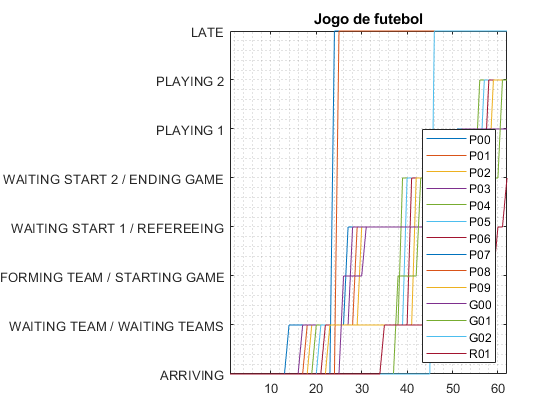

clear all;
read = readcell("files\run2000");
results = cell2mat(read(3:length(read(:,1))-1,:));
waits = (1:length(results(:,1)));
for p = 1:length(results(1,:))
    plot(waits,results(:,p));
    hold on;
end
hold off;
grid("minor");
lgd = legend(read(2,:));
lgd.Location = 'southeast';
title("Jogo de futebol");
ay = gca;
states = ["ARRIVING","WAITING TEAM / WAITING TEAMS","FORMING TEAM / STARTING GAME","WAITING START 1 / REFEREEING","WAITING START 2 / ENDING GAME","PLAYING 1","PLAYING 2","LATE"];
ay.YTickLabel = states;
yticks(0:length(states));
axis(ay,"tight");